clc;
clear all;
clf;

*Declaring all the lengths of the links*

l1 = 320; 
l2 = 100; 
l3 = 300; 
l3_1 = 100;
l4 = 300;
l4_1 = 450;
l5 = 500;

*DOF = theta (one input parameter)*

*Giving the value of theta from 0 to 720 degrees to move in steps of 5 and later converting theta from degree to radians*

thetaDegreesArray = 0:5:720; 
thetaRadiansArray = thetaDegreesArray*(pi/180.0);
thetaInitial = thetaRadiansArray(1);

*Delaring the known points, here point O and point C which are the grounded points*

pointO = [0; 0];
pointC = [0 ; -l1]; 

*Finding point A *

pointA = pointO + l2*[cos(thetaInitial); sin(thetaInitial)];

*Finding point B using Circle - Circle Intersection *

[pointB1, pointB2] = CircleCircleIntersection(pointA, l3, pointC, l4);

*Choosing one of the solutions as the branch of point B. *

*One is to the left and one is to the right, here, we use the one to the right which is point B1*

pointB = pointB1;

*Finding point R using Line - Circle Intersection*

[pointR1, pointR2] = LineCircleIntersection(pointA, pointB, pointA, l3_1);

*Choosing one of the solutions as the branch of point R*

pointR = pointR1;

*Finding point S using Triangular law of vector addition,*

pointS = (((pointB - pointC)/(norm(pointB - pointC)))*l4_1) + pointC;

*Finding point F using Triangular law of vector addition,*

pointF = (((pointS - pointR)/(norm(pointS - pointR)))*l5) + pointR;

*Creating arrays for the trace*

pointATrace = zeros(1,2);
pointBTrace = zeros(1,2);
couplerMidpointTrace = zeros(2,1);

*Code for Animation*

*To have a square shaped inner canvas*

%set(gcf,'Position',[100 100 720 700]) 
grid on
%axis equal
for index = 1:length(thetaRadiansArray)
    theta = thetaRadiansArray(index);    
    
    pointA = pointO + l2*[cos(theta); sin(theta)];
    
    [pointB1, pointB2] = CircleCircleIntersection(pointA, l3, pointC, l4);
    distBetweenPrevBandB1 = norm(pointB-pointB1);
    distBetweenPrevBandB2 = norm(pointB-pointB2);
    %Choose the solution that is nearest to the previous point B
    if(distBetweenPrevBandB1 < distBetweenPrevBandB2)
        pointB = pointB1;
    else
        pointB = pointB2;
    end 
    
    [pointR, pointR2] = LineCircleIntersection(pointA, pointB, pointA, l3_1);
    pointR = [pointR(1) ; pointR(2)];
    
    pointS = (((pointB - pointC)/(norm(pointB - pointC)))*l4_1) + pointC;
    
    pointF = (((pointS - pointR)/(norm(pointS - pointR)))*l5) + pointR;
    

*Code for trace of Point R*

    couplerMidpointTraceXArray(index) = pointR(1);
    couplerMidpointTraceYArray(index) = pointR(2);

*Code for trace of Point F*

    couplerMidpointTraceXArray1(index) = pointF(1);
    couplerMidpointTraceYArray1(index) = pointF(2);  
    hold off;

*Draw the axis in Brown color*

    Brown = '#964B00';
    BrownColor = sscanf(Brown(2:end),'%2x%2x%2x',[1 3])/255;
    
    plot([-141 564], [0 0], 'color', BrownColor, 'LineWidth', 1)
    hold on
    plot([0 0], [-350 160], 'color', BrownColor, 'LineWidth', 1)
    hold on

*Plot all the lines*

    Orange = '#FF6700';
    OrangeColor = sscanf(Orange(2:end),'%2x%2x%2x',[1 3])/255;
    
    Purple = '#800080';
    PurpleColor = sscanf(Purple(2:end),'%2x%2x%2x',[1 3])/255;
    
    plot([pointO(1) pointA(1)], [pointO(2) pointA(2)], 'g-', 'LineWidth', 4);
    hold on;
    plot(pointO(1), pointO(2), 'b-o', 'LineWidth', 4);
    hold on;
    plot([pointA(1) pointB(1)], [pointA(2) pointB(2)], 'color', OrangeColor, 'LineWidth', 4);
    hold on;
    plot([pointB(1) pointC(1)], [pointB(2) pointC(2)], 'm-', 'LineWidth', 4);
    hold on;
    plot([pointC(1) pointS(1)], [pointC(2) pointS(2)], 'r-', 'LineWidth', 4);
    hold on;
    plot([pointR(1) pointF(1)], [pointR(2) pointF(2)], 'color', PurpleColor, 'LineWidth', 4);
    hold on;
    plot(pointR(1), pointR(2), 'b*', 'MarkerSize', 10);
    hold on;
    plot([pointO(1) pointC(1)], [pointO(2) pointC(2)], 'k-', 'LineWidth', 4);  
    hold on;

*Plot all the points*

    plot(pointO(1), pointO(2), 'b-o', 'LineWidth', 5);
    text(-50, 30, '  O', 'Color' , 'black' , 'FontSize' ,12)
    
    plot(pointA(1), pointA(2), 'b-o', 'LineWidth', 5);
    text(pointA(1)+cosd(45), pointA(2)+sind(45), '   A', 'Color' , 'black' , 'FontSize' ,12)
    
    plot(pointB(1), pointB(2), 'b-o', 'LineWidth', 5);
    text(pointB(1), pointB(2), '   B', 'Color' , 'black' , 'FontSize' ,12)
    
    plot(pointC(1), pointC(2), 'b-o', 'LineWidth', 5);
    text(-65, -350, '    C', 'Color' , 'black' , 'FontSize' ,12)
    
    plot(pointS(1), pointS(2), 'b-o', 'LineWidth', 5);
    text(pointS(1), pointS(2), '      S', 'Color' , 'black' , 'FontSize' ,12)
    
    plot(pointF(1), pointF(2), 'b-o', 'LineWidth', 5);
    text(pointF(1), pointF(2), '   F', 'Color' , 'black' , 'FontSize' ,12)
   
    plot(pointR(1), pointR(2), 'b-o', 'LineWidth', 5);
    text(pointR(1), pointR(2), '    R', 'Color' , 'black' , 'FontSize' ,12)

*Trace point R and point F*

    Grey = '#808080';
    GreyColor = sscanf(Grey(2:end),'%2x%2x%2x',[1 3])/255; 
   
    plot(couplerMidpointTraceXArray, couplerMidpointTraceYArray, 'color', GreyColor, 'LineWidth', 1);
    
    plot(couplerMidpointTraceXArray1, couplerMidpointTraceYArray1, 'color', GreyColor, 'LineWidth', 1);

*Draw and plot the slider*

    DarkGreen = '#006400';
    DarkGreenColor = sscanf(DarkGreen(2:end),'%2x%2x%2x',[1 3])/255;
    
    angle = (pointF-pointR)/norm(pointF-pointR);
    thetasliding = atan2(angle(2),angle(1));
    s1 = [pointS(1) + 50*cos(thetasliding+(pi/4))   ; pointS(2) + 50*sin(thetasliding+(pi/4))];
    s2 = [pointS(1) + 50*cos(thetasliding+(3*pi/4)) ; pointS(2) + 50*sin(thetasliding+(3*pi/4))];
    s3 = [pointS(1) + 50*cos(thetasliding-(3*pi/4)) ; pointS(2) + 50*sin(thetasliding-(3*pi/4))];
    s4 = [pointS(1) + 50*cos(thetasliding-(pi/4))   ; pointS(2) + 50*sin(thetasliding-(pi/4))];
    plot([s1(1) s2(1) s3(1) s4(1) s1(1)], [s1(2) s2(2) s3(2) s4(2) s1(2)], 'color', DarkGreenColor, 'LineWidth', 3);
    hold on      

*Give labels for the x and y axis and also a title for our animation and figure*

    title('Six bar linkage (Inverted slider crank kinematic chain connected in parallel with a four bar linkage)', 'FontSize', 10);
    xlabel('X-Axis', 'FontSize', 10);
    ylabel('Y-Axis', 'FontSize', 10)

*Use "drawnow()" command to animate*

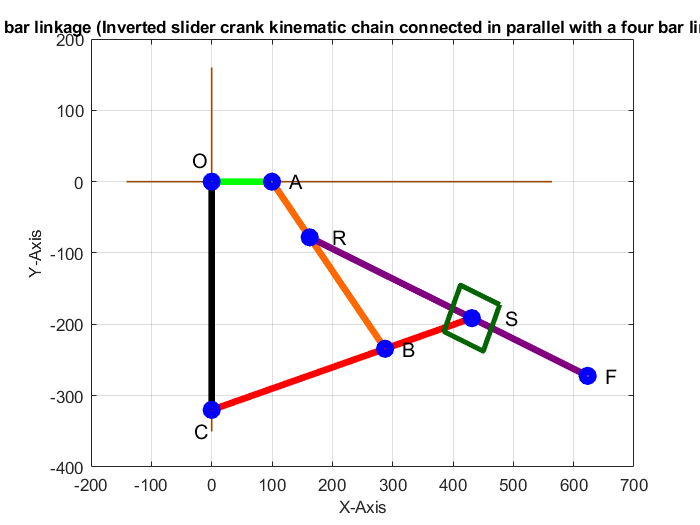

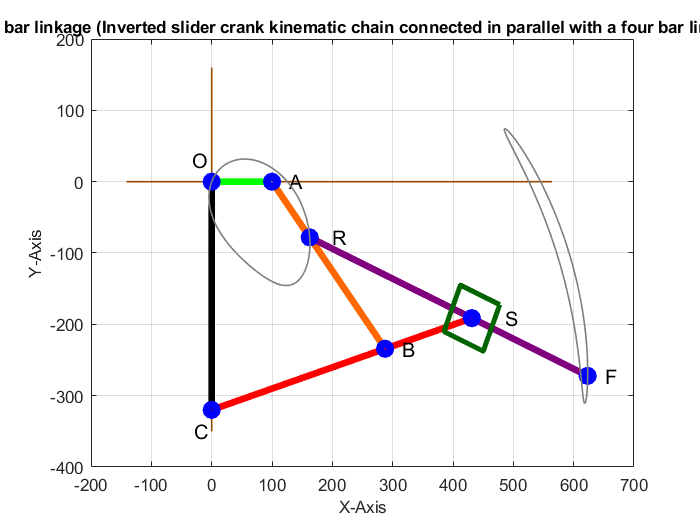

    drawnow(); 
    grid on
    %pause(0.001);
end